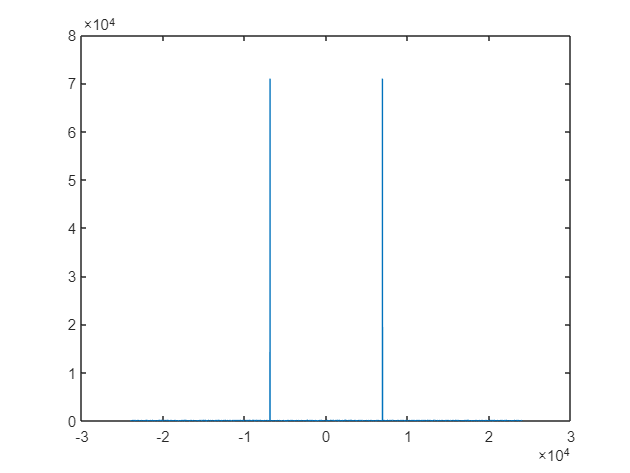

load("Observation_nb.mat")
%frequency domain
f=-23999:24000;
y_1=fftshift(abs(fft(real(y(:,1)))));
plot(f,y_1)

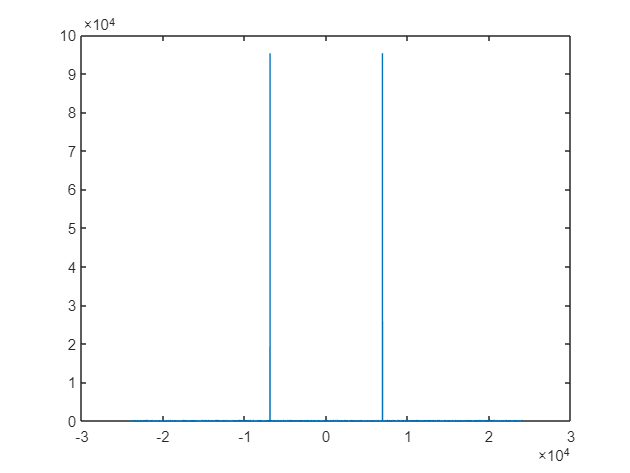


f=-23999:24000;
y_2=fftshift(abs(fft(real(y(:,2)))));
plot(f,y_2)


f=-23999:24000;
y_3=fftshift(abs(fft(real(y(:,3)))));
plot(f,y_3)


f=-23999:24000;
y_4=fftshift(abs(fft(real(y(:,4)))));
plot(f,y_4)

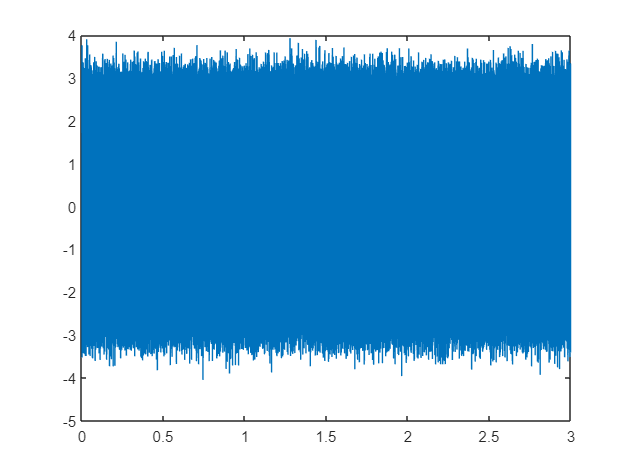


%time domain
t=1/16000:1/16000:3;
y1=y(:,1);
plot(t,y1)

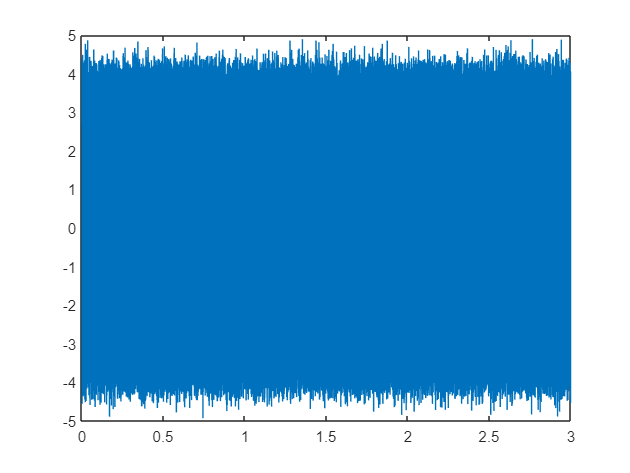


t=1/16000:1/16000:3;
y2=y(:,2);
plot(t,y2)


t=1/16000:1/16000:3;
y3=y(:,3);
plot(t,y3)


t=1/16000:1/16000:3;
y4=y(:,4);
plot(t,y4)


%find center frequency
fc=6899/3 %hz %换算单位 从0-24000换到0-8000hz

fc = 2.2997e+03


%求协方差矩阵 Rx 
Xk=[fft(y(:,1)),fft(y(:,2)),fft(y(:,3)),fft(y(:,4))];
Xk_t=Xk.';
Xk

Xk = 	1.0e+05 *

  -0.0007 - 0.0000i  -0.0007 - 0.0000i  -0.0007 + 0.0000i  -0.0007 + 0.0000i
   0.0001 - 0.0004i   0.0001 - 0.0004i   0.0001 - 0.0004i   0.0001 - 0.0004i
  -0.0001 - 0.0000i  -0.0001 - 0.0000i  -0.0001 - 0.0000i  -0.0001 - 0.0000i
   0.0003 + 0.0001i   0.0003 + 0.0001i   0.0003 + 0.0001i   0.0003 + 0.0001i
  -0.0000 + 0.0001i  -0.0000 + 0.0001i  -0.0000 + 0.0001i  -0.0000 + 0.0001i
  -0.0001 - 0.0003i  -0.0001 - 0.0003i  -0.0001 - 0.0003i  -0.0001 - 0.0003i
  -0.0005 - 0.0001i  -0.0005 - 0.0001i  -0.0005 - 0.0001i  -0.0005 - 0.0001i
   0.0002 + 0.0002i   0.0002 + 0.0002i   0.0002 + 0.0002i   0.0002 + 0.0002i
  -0.0001 - 0.0001i  -0.0001 - 0.0001i  -0.0001 - 0.0001i  -0.0001 - 0.0001i
  -0.0001 + 0.0007i  -0.0001 + 0.0007i  -0.0001 + 0.0007i  -0.0001 + 0.0007i


Rx=(Xk_t*Xk_t')/48000;
Rx

Rx = 	1.0e+05 *

   4.1254 + 0.0000i   3.5239 - 1.6034i   1.9967 - 3.0321i   0.1551 - 3.9046i
   3.5239 + 1.6034i   4.1274 + 0.0000i   3.5249 - 1.6035i   1.9967 - 3.0321i
   1.9967 + 3.0321i   3.5249 + 1.6035i   4.1274 + 0.0000i   3.5239 - 1.6034i
   0.1551 + 3.9046i   1.9967 + 3.0321i   3.5239 + 1.6034i   4.1254 + 0.0000i


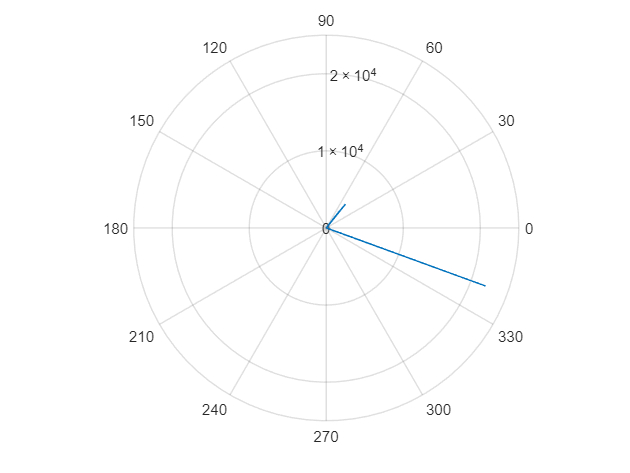



[V,D]=eig(Rx);
[d,ind]=sort(diag(D));
vector1=V(:,ind(1));
vector2=V(:,ind(2));
Un=[vector1,vector2];
%算a(theta)
angle_p=zeros(1,181);
p_value_1=zeros(1,181);
p_value_2=zeros(1,181);
a=1;
for theta=-pi/2:pi/180:pi/2;
    a_theta_1=zeros(1,4);        %time_difference = d'*v./340;
    a_theta_2=zeros(1,4);        %a_theta = exp(-j*2*pi*time_difference*2300).';  
    
    for J=1:4;
        a_theta_1(1,J)=exp((-i*2*pi*((J-1)*0.034-0.051)*sin(theta))/(340/fc));
        
    end 
    a_theta_t_1=a_theta_1.';    
    p_theta_1=1/((a_theta_t_1')*Un*(Un')*a_theta_t_1);
    p_value_1(a)=p_theta_1;

  
    angle_p(a)=theta;
    a=a+1;
end
polarplot(angle_p,real(p_value_1))

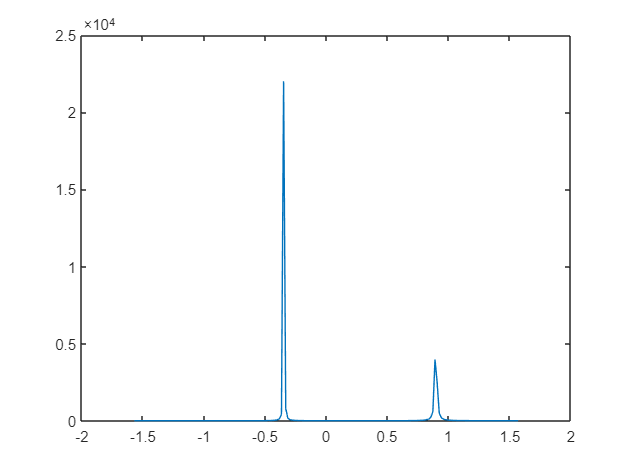

plot(angle_p,real(p_value_1))




p_value=p_value_1';
theta = -90:1:90;    

P_middle = abs(p_value(2:end-1));
P_front = abs(p_value(1:end-2));
P_back = abs(p_value(3:end));
logic_front = (P_middle - P_front)>0;
logic_back = (P_middle - P_back)>0;
logic = logic_front & logic_back;
P_middle(~logic) = min(P_middle);
P_local = [abs(p_value(1));P_middle;abs(p_value(end))];
[~,doa_Idx] = maxk(P_local,2);
doa = theta(doa_Idx);
[~,minIdx] = min(abs(doa));
doa_source = doa(minIdx);
[~,maxIdx] = max(abs(doa));
interfer = doa(maxIdx);
disp(['The desired source DOA with MUSIC is: ',num2str(doa_source),' deg']);

The desired source DOA with MUSIC is: -20 deg


disp(['The interfering DOA with MUSIC is: ',num2str(interfer),' deg']);

The interfering DOA with MUSIC is: 51 deg
